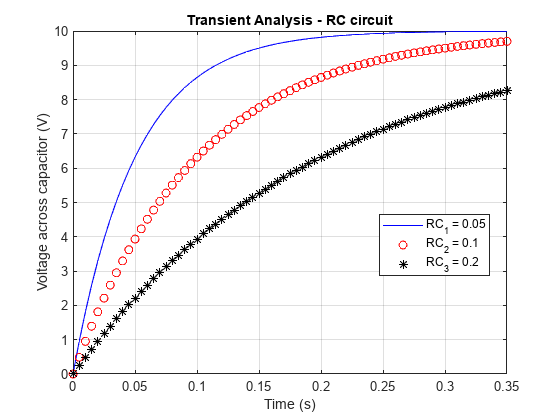

clear
% Define the voltage source
Vs = 10;
% Define the capacitor in the circuit
C = 10e-6;
% Define the time lapse that we're going to explore
t = 0 : 0.005 : 0.35;
 

% Define the resistors in each time constant and
% calculate the voltage across the capacitor
R1 = 5e3;
tau1 = R1*C;
V1 = Vs * ( 1 - exp(-t/tau1) );
 

R2 = 10e3;
tau2 = R2*C;
V2 = Vs * ( 1 - exp(-t/tau2) );
 

R3 = 20e3;
tau3 = R3*C;
V3 = Vs * ( 1 - exp(-t/tau3) );
 

% Plot the responses, all at once
figure
plot(t, V1, 'b-', t, V2, 'ro', t, V3, 'k*')
grid on
title('Transient Analysis - RC circuit')
xlabel('Time (s)')
ylabel('Voltage across capacitor (V)')
legend(['RC_1 = ' num2str(tau1)],...
       ['RC_2 = ' num2str(tau2)],...
       ['RC_3 = ' num2str(tau3)], 'location', 'best')


% Given constants
vs = 10;

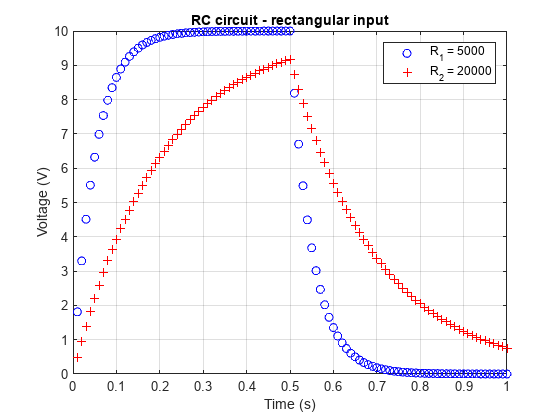

c = 10e-6; 

% Case 1. R = 5k ohms
r1 = 5e3;
[v1, t1] = rectangular_RC(vs, r1, c); 

% Case 2. R = 20k ohms
r2 = 20e3;
[v2, t2] = rectangular_RC(vs, r2, c); 

% Plot the responses
figure
plot(t1, v1, 'bo', t2, v2, 'r+')
grid on 

% Add labels
title('RC circuit - rectangular input')
xlabel('Time (s)')
ylabel('Voltage (V)')
legend(['R_1 = ' num2str(r1)], ...
       ['R_2 = ' num2str(r2)])

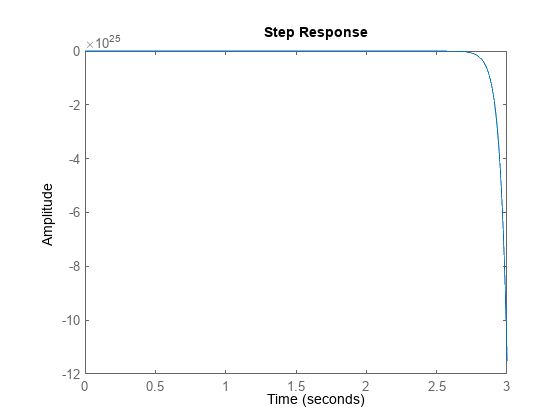

sys=tf([1],[-R1*C 1]);
step(sys)

R =10

R = 10

C =10

C = 10

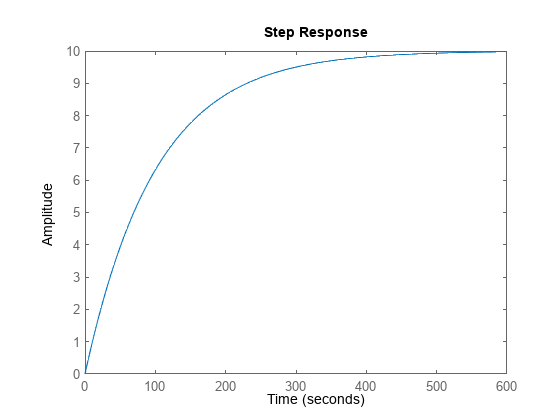

A=[-1/(R*C) 1/(R*C);0 0];
B=[1/C;0];
C=[1,0];
D=0;

sys=ss(A,B,C,D);
figure
step(sys)

function [v, t] = rectangular_RC(vs, r, c)
tau = r * c; 

% First half of the pulse: 0.01 to 0.5 seconds
% Use the correct formula.
t1 = linspace(.01, 0.5, 50);
v1 = vs * (1 - exp(-t1/tau)); 

% Second half of the pulse: 0.51 to 1 seconds.
% Take into account the max voltage reached.
% Use the appropriate formula.
Vm = v1(end);
t2 = linspace(0.51, 1, 50);
v2 = Vm * exp(-t1/tau); 
% Assemble the final vectors to return
t = [t1 t2];
v = [v1 v2];
end